clear
clc
close all
% 弹体气动数据
V = 914.4;
a1 = 1.5;
a2 = -250;
a3 = 280;
a4 = 1.6;
a5 = 0.23;

kv = V/(57.3*9.8);

A1 = a1+a4;
A2 = a2+a1*a4;

omega_n = 5.15;
omega_n1 = 28.23;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -1.4812

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -0.9096


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4 0], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
  -0.9096 s^3 - 2.82 s^2 + 225.2 s
  --------------------------------
  s^3 + 34.41 s^2 + 201 s + 748.7
 
连续时间传递函数。
模型属性


step(G_deltabar_nye,1)
omega_n = 6.05;
omega_n1 = 31.5;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -2.2809

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -1.4007


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4 0], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
  -1.401 s^3 - 4.342 s^2 + 346.8 s
  --------------------------------
  s^3 + 38.76 s^2 + 265.3 s + 1153
 
连续时间传递函数。
模型属性


hold on
step(G_deltabar_nye,1)

omega_n = 6.25;
omega_n1 = 35.86;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -2.7711

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -1.7017


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4 0], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
  -1.702 s^3 - 5.275 s^2 + 421.4 s
  --------------------------------
   s^3 + 43.36 s^2 + 308 s + 1401
 
连续时间传递函数。
模型属性


hold on
step(G_deltabar_nye,1)

omega_n = 5.76;
omega_n1 = 41.17;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -2.7021

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -1.6594


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4 0], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
  -1.659 s^3 - 5.144 s^2 + 410.9 s
  --------------------------------
  s^3 + 48.08 s^2 + 317.7 s + 1366
 
连续时间传递函数。
模型属性


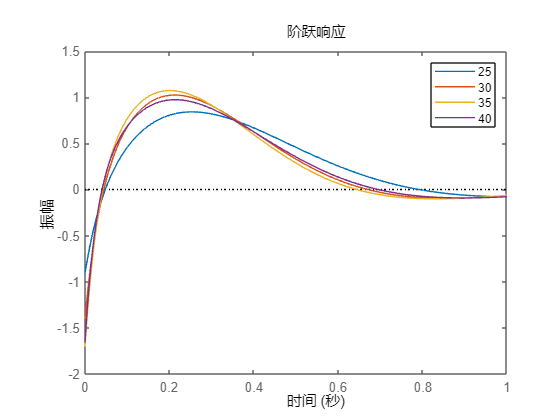

hold on
step(G_deltabar_nye,1)
legend('25','30','35','40')
xlim([0,1])